**DARPA SUBOFF Sail**

Sail forebody length                                            =0.325521 Ft

Sail Parallel Middle Body Length                         =0.200521 Ft

Sail Afterbody length                                           =0.682292 Ft

Sail Total Length                                                 =1.208333 Ft

Span of Sail with uniform Profile                         =0.674479 Ft

Zmax= one half of the maximum sail thickness  =0.109375 Ft

**Main Dimension**

% Define sail dimensions
L_Sail_forebody_ft = 0.325521; % Sail forebody length in feet
L_parallel_middle_ft = 0.200521; % Sail parallel middle body length in feet
L_afterbody_ft = 0.682292; % Sail afterbody length in feet
L_total_ft = 1.208333; % Sail total length in feet
Span_sail_ft = 0.674479; % Span of sail with uniform profile in feet
Zmax = 0.109375; % One half of the maximum sail thickness in feet

**Sail Forebody**

% Calculate sail surface points
% 3.032986 Ft <= X <= 3.358507 Ft
% y<= 1.507813 Ft
DivisionsSailFore = 60;
StepSailFore = L_Sail_forebody_ft / DivisionsSailFore;
XSailFore= 3.032986:StepSailFore:3.358507;
% Calculate Z1Fore
D = 3.072 * (XSailFore - 3.032986);
A = 2 * D .* (D - 1).^4;
B = (1/3) * (D.^2) .* (D - 1).^3;
C = 1 - ((D - 1).^4) .* (4 * D + 1);
Z1Fore = Zmax * ((2.094759 .* A) + (0.2071781 .* B) + C).^0.5;

**Sail Parallel Middlebody**

% ... (Sail Parallel Middlebody)
%3.358507 Ft <= X <= 3.559028
%y<=1.507813
DivisionsSailParallel = 60;
StepSailParallel=(3.559028-3.358507)/DivisionsSailParallel;
% ... (Sail Parallel Middlebody calculations)
% y <= 1.507813 Ft
XSailParallel= 3.358507:StepSailParallel:3.559028;
ZSailParallel=ones(1, DivisionsSailParallel + 1) * Zmax;

**Sail Afterbody**

% (Sail Afterbody calculations)
%(Revised 11 January 1989)
%For 3.559028 Ft <= x <= 4.241319 Ft
%y <= 1.507813 Ft
DivisionsSailAft = 60;
StepSailAft=(4.241319-3.559028)/DivisionsSailAft;
XSailAft=3.559028:StepSailAft:4.241319;
E  = (4.241319 - XSailAft) / 0.6822917;
Z1SailAft=Zmax * ((2.238361 .* E .* ((E-1).^4))+(3.106529 .* (E .^2) .* ((E-1) .^3))+(1-((E-1) .^4) .* (4.*E +1)));

**Sail CapFore**

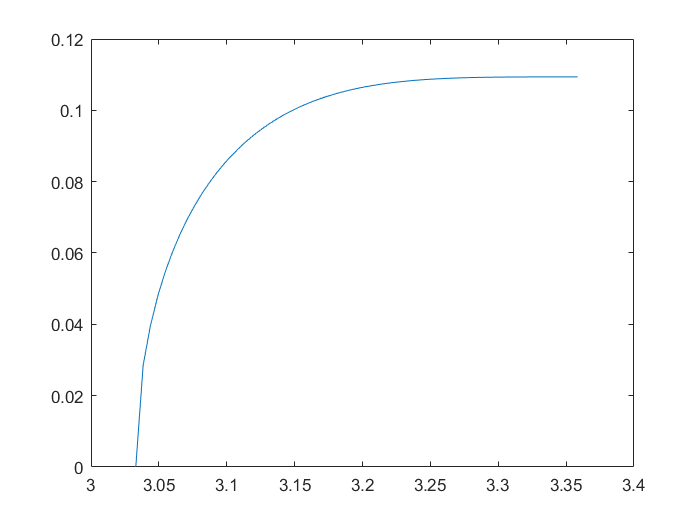

% Sail CapFore
XSailCapFore = XSailFore;
ZSailCapFore = Z1Fore;

% Calculate Ymin and Ymax
Ymin = 1.507813;
Ymax = (ZSailCapFore / 2) + 1.507813;
Ydivision = 60;
YmaxElement = max(Ymax);
Ystep = (YmaxElement - Ymin) / Ydivision;
% Initialize an empty matrix Y
Y = zeros(Ydivision, numel(Ymax));

% Fill the first row with Ymin
Y(1, :) = Ymin;

% Fill the last row with Ymax
Y(end, :) = Ymax;

% Fill the remaining rows with values increasing from Ymin to Ymax
for i = 2:Ydivision-1
    % Calculate the current row values based on Ymin and Ymax
    Y(i, :) = Ymin + (i-1) * (Ymax - Ymin) / (Ydivision - 1);
end
Y0=Y;
% Create Z1 matrix
Z1 = repmat(ZSailCapFore, 60, 1);
plot(XSailCapFore,ZSailCapFore)

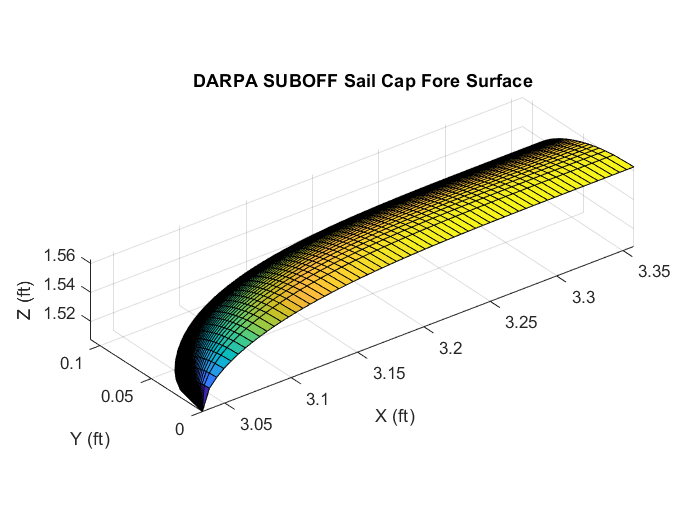

% Create Z2 matrix
Z2 = real((Z1.^2 - (2*(Y - 1.507813)).^2).^0.5);

% Create X matrix
X = repmat(XSailCapFore, 60, 1);
Y=Z2;
Z=Y0;
% Plot the surface
surf(X, Y, Z)
axis equal;
xlabel('X (ft)');
ylabel('Y (ft)');
zlabel('Z (ft)');
title('DARPA SUBOFF Sail Cap Fore Surface');

% Reshape X, Y, and Z matrices into vertical vectors
X_vector = X(:);
Y_vector = Y(:);
Z_vector = Z(:);

% Concatenate X, Y, and Z vectors into a single matrix
data_matrix = [X_vector, Y_vector, Z_vector];

% Save the concatenated matrix as a CSV file
csvwrite('XYZ_data_Cap_fore.csv', data_matrix)


SailCap Middle

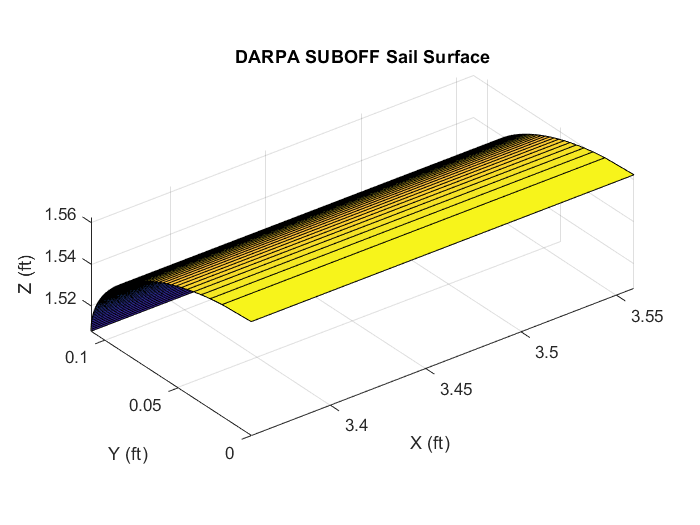

%3.358507 Ft <= X <= 3.559028
X1=3.358507; 
X2=3.559028;
Z1=ones(1, 2) * Zmax;
%1.507813 Ft <y I (ZI/2) + 1.507813 Ft
Ymin=1.507813;
Ymax=(Zmax/2) + Ymin;
Ydivision = 60;
Ystep = (Ymax- Ymin) / Ydivision;
Y1=[Ymin:Ystep:Ymax];
Z = repmat(Y1, 2, 1);

X=[X1*ones(size(Y1)); X2*ones(size(Y1))];
Z2 = sqrt(Zmax^2 - (2*(Y1-1.507813)).^2);
Y= repmat(Z2, 2, 1);

surf(X,Y,Z)
axis equal
xlabel('X (ft)');
ylabel('Y (ft)');
zlabel('Z (ft)');
title('DARPA SUBOFF Sail Surface');

% Reshape X, Y, and Z matrices into vertical vectors
X_vector = X(:);
Y_vector = Y(:);
Z_vector = Z(:);

% Concatenate X, Y, and Z vectors into a single matrix
data_matrix = [X_vector, Y_vector, Z_vector];

% Save the concatenated matrix as a CSV file
csvwrite('XYZ_data_Cap_middle.csv', data_matrix)

SailCapAft

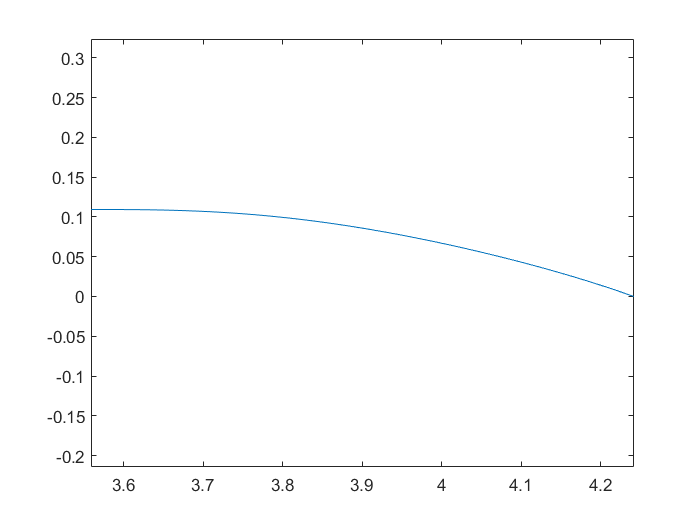

% (Sail Afterbody calculations)
%(Revised 11 January 1989)
%For 3.559028 Ft <= x <= 4.241319 Ft
%y <= 1.507813 Ft
X=XSailAft;
Z1=Z1SailAft;
% Calculate Ymin and Ymax
Ymin = 1.507813;
Ymax = (Z1 / 2) + 1.507813;
Ydivision = 60;
YmaxElement = max(Ymax);
Ystep = (YmaxElement - Ymin) / Ydivision;
% Initialize an empty matrix Y
Y = zeros(Ydivision, numel(Ymax));

% Fill the first row with Ymin
Y(1, :) = Ymin;

% Fill the last row with Ymax
Y(end, :) = Ymax;

% Fill the remaining rows with values increasing from Ymin to Ymax
for i = 2:Ydivision-1
    % Calculate the current row values based on Ymin and Ymax
    Y(i, :) = Ymin + (i-1) * (Ymax - Ymin) / (Ydivision - 1);
end
Y0=Y;
% Create Z1 matrix
Z1 = repmat(Z1, 60, 1);
plot(X,Z1SailAft)
axis equal

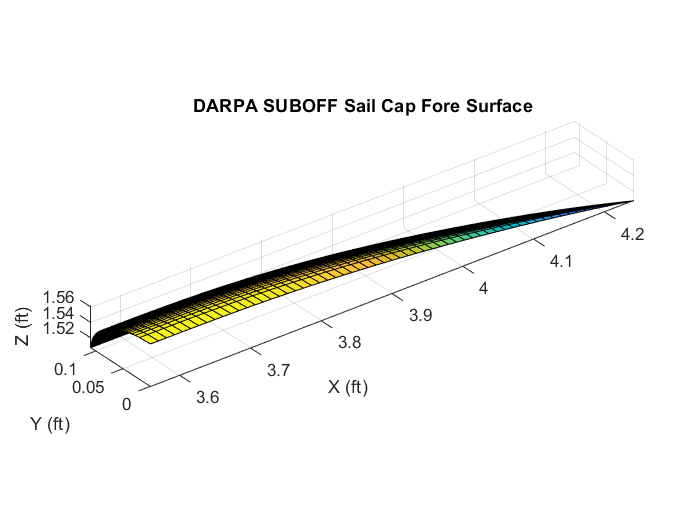

% Create Z2 matrix
Z2 = real((Z1.^2 - (2*(Y - 1.507813)).^2).^0.5);

% Create X matrix
X = repmat(X, 60, 1);
Y=Z2;
Z=Y0;
% Plot the surface
surf(X, Y, Z);
axis equal;
xlabel('X (ft)');
ylabel('Y (ft)');
zlabel('Z (ft)');
title('DARPA SUBOFF Sail Cap Fore Surface');

% Reshape X, Y, and Z matrices into vertical vectors
X_vector = X(:);
Y_vector = Y(:);
Z_vector = Z(:);

% Concatenate X, Y, and Z vectors into a single matrix
data_matrix = [X_vector, Y_vector, Z_vector];

% Save the concatenated matrix as a CSV file
csvwrite('XYZ_data_Cap_aft.csv', data_matrix)